%% ========================================================================
%  SIM_03_TwoSat_ControlledTarget
%  --------------------------------------------------------------
%  - Uses CVX optimization to control Follower 1 to a target position.
%  - Minimizes total ΔV while obeying Clohessy-Wiltshire (CW) equations.
%  - Follower 2 remains uncontrolled for comparison.
%  - Plots both trajectories and control effort (ΔV) over time.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === PARAMETERS ===
mu = 3.986e14;            % Earth's gravitational parameter (m^3/s^2)
Re = 6371e3;              % Earth radius (m)
alt = 500e3;              % Orbital altitude (m)
a = Re + alt;             % Semi-major axis (m)
n = sqrt(mu / a^3);       % Mean motion (rad/s)

T = 2*pi / n;             % Orbital period (s)
N_orbits = 1;             % Simulate for 1 orbit

% Time settings
dt = 10;                                % Time step (s)
N = round(N_orbits * T / dt);           % Number of time steps
t_vec = (0:N-1)*dt;                     % Time vector for plotting

%% === INITIAL STATES ===
x0_follower1 = [0; 100; 0; 0; 0.1; 0];      % Controlled satellite
x0_follower2 = [0; -100; 50; 0; -0.05; 0];  % Passive drift for comparison
x_target = [0; 0; 0; 0; 0; 0];              % Target for Follower 1

%% === CW SYSTEM MATRICES ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

B = [zeros(3); eye(3)];  % Control matrix (thrust applies to acceleration)

%% === CVX OPTIMIZATION ===
cvx_begin quiet
    variables x(6, N) u(3, N-1)
    
    % Minimize total DeltaV
    minimize( sum(norms(u, 2, 1)) )

    % Constraints
    subject to
        x(:,1) == x0_follower1;   % Initial condition
        x(:,N) == x_target;       % Final condition
        
        for k = 1:N-1
            x(:,k+1) == x(:,k) + dt * (A * x(:,k) + B * u(:,k));
        end
cvx_end

%% === DELTAV CALCULATION ===
dV_per_step = vecnorm(u, 2, 1);      % DeltaV magnitude at each step
total_dV = sum(dV_per_step);         % Total DeltaV used
disp(['Total DeltaV used by Follower 1: ', num2str(total_dV), ' m/s'])

Total DeltaV used by Follower 1: 0.2086 m/s


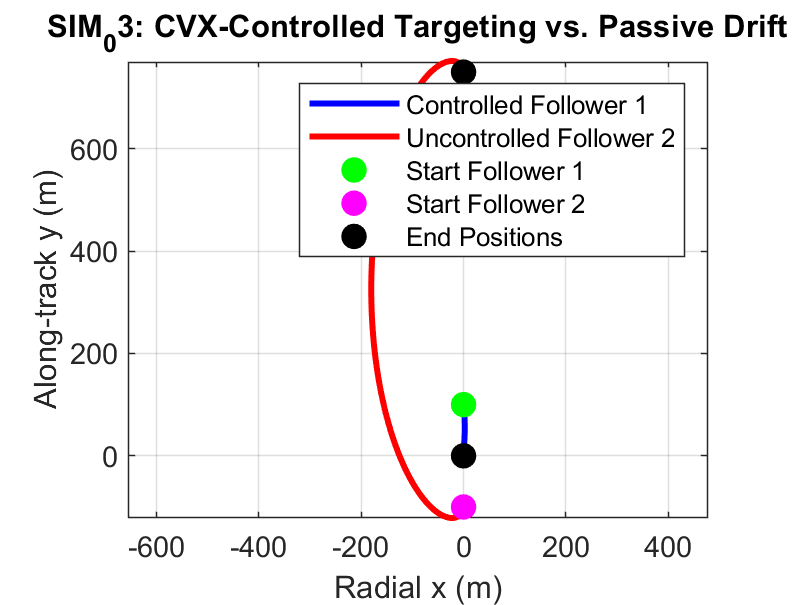


%% === UNCONTROLLED FOLLOWER (for comparison) ===
cw_dynamics = @(t, x) A * x;
[t, x_follower2] = ode45(cw_dynamics, linspace(0, N*dt, N), x0_follower2);
x_follower2 = x_follower2';

%% === PLOT 1: RELATIVE MOTION TRAJECTORIES ===
figure;
plot(x(1,:), x(2,:), 'b', 'LineWidth', 2); hold on;
plot(x_follower2(1,:), x_follower2(2,:), 'r', 'LineWidth', 2);
plot(x(1,1), x(2,1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');  % Start Follower 1
plot(x_follower2(1,1), x_follower2(2,1), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');  % Start Follower 2
plot(x(1,end), x(2,end), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % End Follower 1
plot(x_follower2(1,end), x_follower2(2,end), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');  % End Follower 2
xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM 03: CVX-Controlled Targeting vs. Passive Drift');
legend('Controlled Follower 1', 'Uncontrolled Follower 2', ...
       'Start Follower 1', 'Start Follower 2', 'End Positions');
grid on; axis equal;
saveas(gcf, 'SIM_03_TwoSat_ControlledTarget.png');

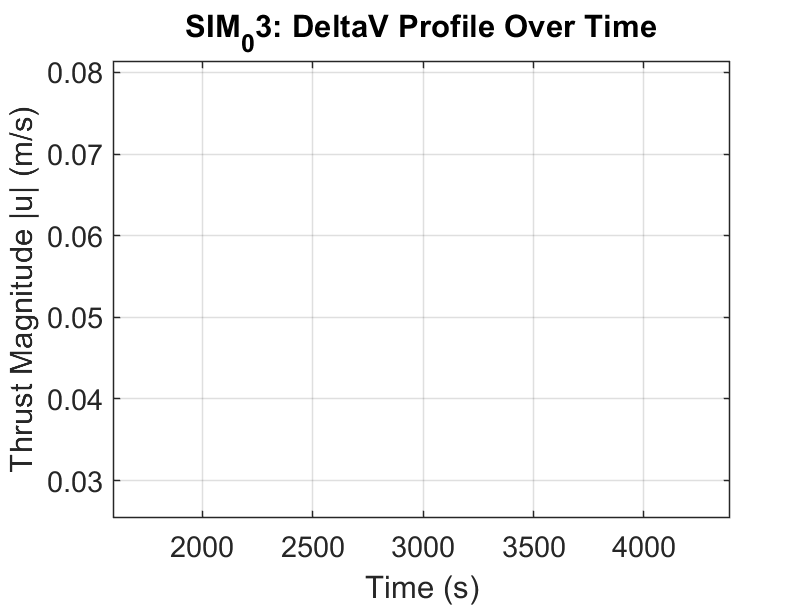


%% === PLOT 2: DELTAV PROFILE ===
figure;
plot(t_vec(1:end-1), dV_per_step, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Thrust Magnitude |u| (m/s)');
title('SIM 03: DeltaV Profile Over Time');
grid on;
saveas(gcf, 'SIM_03_TwoSat_ControlledTarget_DeltaV.png');


%% === END ===
disp('Simulation completed: SIM_03_TwoSat_ControlledTarget');

Simulation completed: SIM_03_TwoSat_ControlledTarget
